data=acc_data;
x = data(:,1);
y = data(:,2);
z = data(:,3);

%% 最小二乘法参数估计
N = length(data);
M = zeros(N, 6);
p = zeros(N, 1);

for k = 1:N
    M(k,:) = [y(k)^2 z(k)^2 x(k) y(k) z(k) 1];          % 矩阵M
    p(k) = -x(k)^2;                                     % 向量p
end

v = (M'*M)\M' * p;                                 % 计算最优解

x0 = -v(3) / 2;                                         % 拟合出的x0
y0 = -v(4) / (2*v(1));                                  % 拟合出的y0
z0 = -v(5) / (2*v(2));                                  % 拟合出的z0

A = sqrt(x0*x0 + v(1)*y0*y0 + v(2)*z0*z0 - v(6));       % 拟合出的x方向上的轴半径A
B = A/sqrt(v(1));                                       % 拟合出的y方向上的轴半径B
C = A/sqrt(v(2));                                       % 拟合出的z方向上的轴半径C

cali_data = zeros(size(data));
scale = [A, B, C];                               % 尺度因子
offset = [x0, y0, z0];                                  % 偏移
for k = 1:N
    cali_data(k,:) = 1 ./ scale .* (data(k,:) - offset);         % 校准结果
end

[x, y, z] = ellipsoid(x0,y0,z0,A,B,C,50);

figure();
plot3(acc_data(:,1),acc_data(:,2),acc_data(:,3));
xlim([-1.5 1.5])
ylim([-1.5 1.5])
zlim([-1.5 1.5])
hold on;
surfl(x,y,z);

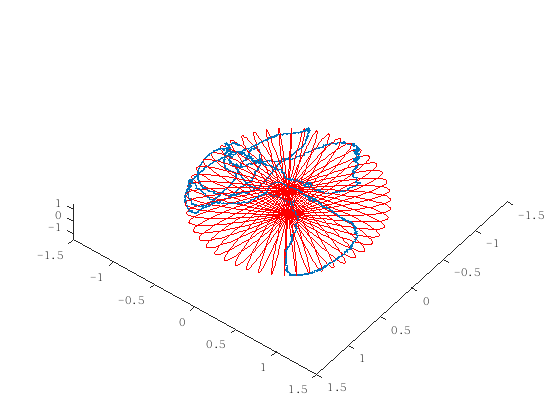

figure();
plot3(acc_data(:,1),acc_data(:,2),acc_data(:,3));
xlim([-1.5 1.5])
ylim([-1.5 1.5])
zlim([-1.5 1.5])
hold on;
plot3(x,y,z,'Color','r');